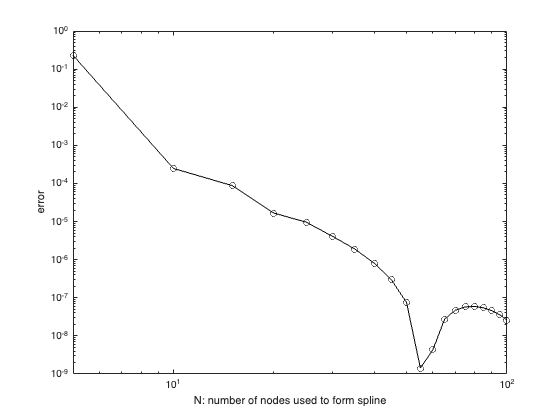

clear 
% convince Sontosh that built in matlab cubic spline is 3rd accurate.
% convince Sontosh that the built in spline command in the toolbox is 
% hermite splines: order 5.

f = @(x) exp(-x).*sin(pi*x);
a = -1; b = 2;
z = a + (b-a)*rand ; % random number between a and b

%N = 5; % number of data points
K = 20;
for k = 1:K
    N = 5*k;
    x = linspace(a,b,N);
    fx = f(x);
    p = spline(x,fx,z); % cubic hermite spline
    %p = interp1(x,fx,z,'cubic'); % cubic spline
    err(k) = abs(p - f(z));
end

figure(1), clf;
loglog(5*[1:K],err,'ko-')
xlabel('N: number of nodes used to form spline');
ylabel('error');

pfit = polyfit(log(5*[1:K]),log(err),1);
slope = pfit(1)

slope = -5.0919


z

z = 1.4442

err

err =     0.2305    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
